# Problem 3

S = [2, 6, 6, 3, 3, 3, 5, 5, 3, 4, 6, 3, 2, 3, 6, 4];
a = [-2, 1.5, 0, 0, -0.5, 1.5, -0.5, 1, -0.25, -1, -0.5, -1.25, 0.125, 0.125, 0.125, 4]

a =    -2.0000    1.5000         0         0   -0.5000    1.5000   -0.5000    1.0000   -0.2500   -1.0000   -0.5000   -1.2500    0.1250    0.1250    0.1250    4.0000


W= [1	-1	0	0	0	0	0	0	0	0	0	0	0	0	0	0
0	0	1	-1	0	0	0	0	0	0	0	0	0	0	0	0
0	0	0	0	1	-1	0	0	0	0	0	0	0	0	0	0
0	0	0	0	0	0	1	-1	0	0	0	0	0	0	0	0
0	0	0	0	0	0	0	0	1	-1	0	0	0	0	0	0
0	0	0	0	0	0	0	0	0	0	1	-1	0	0	0	0
0	0	0	0	0	0	0	0	0	0	0	0	1	-1	0	0
0	0	0	0	0	0	0	0	0	0	0	0	0	0	1	-1
1	1	-1	-1	0	0	0	0	0	0	0	0	0	0	0	0
0	0	0	0	1	1	-1	-1	0	0	0	0	0	0	0	0
0	0	0	0	0	0	0	0	1	1	-1	-1	0	0	0	0
0	0	0	0	0	0	0	0	0	0	0	0	1	1	-1	-1
1	1	1	1	-1	-1	-1	-1	0	0	0	0	0	0	0	0
0	0	0	0	0	0	0	0	1	1	1	1	-1	-1	-1	-1
1	1	1	1	1	1	1	1	-1	-1	-1	-1	-1	-1	-1	-1
1	1	1	1	1	1	1	1	1	1	1	1	1	1	1	1]

W =      1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     1    -1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1    -1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1    -1
     1     1    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1    -1    -1     0     0     0     0     0     0     0     0


a*W

ans =      2     6     6     3     3     3     5     5     3     4     6     3     2     3     6     4


norm(W)

ans = 4

norm_weights = a .* norm(W)

norm_weights =    -8.0000    6.0000         0         0   -2.0000    6.0000   -2.0000    4.0000   -1.0000   -4.0000   -2.0000   -5.0000    0.5000    0.5000    0.5000   16.0000


sorted_norm_weights = sort(abs(norm_weights))

sorted_norm_weights =          0         0    0.5000    0.5000    0.5000    1.0000    2.0000    2.0000    2.0000    4.0000    4.0000    5.0000    6.0000    6.0000    8.0000   16.0000


threshold = sorted_norm_weights(12)

threshold = 5

reduced_weights = norm_weights;
reduced_weights(abs(norm_weights) <= threshold) = 0

reduced_weights =     -8     6     0     0     0     6     0     0     0     0     0     0     0     0     0    16


reconstructed_S = reduced_weights* W/norm(W)

reconstructed_S =     2.0000    6.0000    5.5000    2.5000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    5.5000    2.5000    4.0000    4.0000    4.0000    4.0000


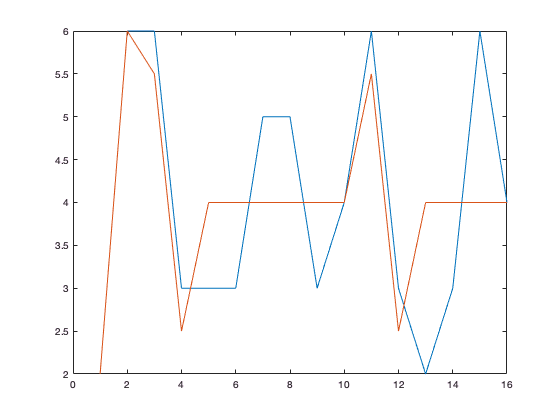

plot(S);
hold on;
plot(reconstructed_S);

Ratio of energy:

sum(abs(reduced_weights))/sum(abs(norm_weights))

ans = 0.6261